clear all;
clc;

%% 1Arc example 
% Load DICOM
path = cd;
DICOM_path = [path,'/example/test_case/VMAT1Arc/0028_VMAT202003181arc.dcm'];
BLD_type = 'agility';
VMAT_PLN_INFO = VMAT_PLAN(DICOM_path);

Total MU:643.489563 
Total control points: 147 
Fractions:28 
Target prescription dose(Gy):61.600000 
This is 1 th control point 
This is 2 th control point 
This is 3 th control point 
This is 4 th control point 
This is 5 th control point 
This is 6 th control point 
This is 7 th control point 
This is 8 th control point 
This is 9 th control point 
This is 10 th control point 
This is 11 th control point 
This is 12 th control point 
This is 13 th control point 
This is 14 th control point 
This is 15 th control point 
This is 16 th control point 
This is 17 th control point 
This is 18 th control point 
This is 19 th control point 
This is 20 th control point 
This is 21 th control point 
This is 22 th control point 
This is 23 th control point 
This is 24 th control point 
This is 25 th control point 
This is 26 th control point 
This is 27 th control point 
This is 28 th control point 
This is 29 th control point 
This is 30 th control point 
This is 31 th control point 
This is 


% calculate Modulation Index of leaf speed VMAT_PLN_INFO.ALS,VMAT_PLN_INFO.SLS
% VMAT_PLN_INFO = MI_leafspeed_TEST(VMAT_PLN_INFO);
VMAT_PLN_INFO = MI_leafspeed(VMAT_PLN_INFO);

% calculate Modulation Index of leaf acceleration
VMAT_PLN_INFO = MI_leafacceleration(VMAT_PLN_INFO);

% calculate Total Modulation Index including gantry acceleration, DR variation, MLC speed, MLC acceleration
% VMAT_PLN_INFO.DOSERATE,VMAT_PLN_INFO.GantrySpeed,VMAT_PLN_INFO.ADR,VMAT_PLN_INFO.SDR
VMAT_PLN_INFO = MI_TotalModulation(VMAT_PLN_INFO);

% calculate aperture perimeter (VMAT_PLN_INFO.AP)
VMAT_PLN_INFO = Aperture_Perimeter(VMAT_PLN_INFO,BLD_type);

rem(start_point,1) ~= 0 && rem(end_point,1) ~= 0
perimeter for 2th control point is 56.660000 cmrem(start_point,1) ~= 0 && rem(end_point,1) ~= 0
perimeter for 5th control point is 82.830000 cmrem(start_point,1) ~= 0 && rem(end_point,1) ~= 0
perimeter for 9th control point is 138.020000 cmrem(start_point,1) ~= 0 && rem(end_point,1) ~= 0
perimeter for 10th control point is 115.290000 cmrem(start_point,1) ~= 0 && rem(end_point,1) ~= 0
perimeter for 11th control point is 124.300000 cmrem(start_point,1) ~= 0 && rem(end_point,1) ~= 0
perimeter for 17th control point is 92.740000 cmrem(start_point,1) ~= 0 && rem(end_point,1) ~= 0
perimeter for 19th control point is 124.880000 cmrem(start_point,1) ~= 0 && rem(end_point,1) ~= 0
perimeter for 26th control point is 73.890000 cmrem(start_point,1) ~= 0 && rem(end_point,1) ~= 0
perimeter for 36th control point is 87.040000 cmrem(start_point,1) ~= 0 && rem(end_point,1) ~= 0
perimeter for 37th control point is 80.800000 cmrem(start_point,1) ~= 0 && re


% calculate aperture area (VMAT_PLN_INFO.AA)
VMAT_PLN_INFO = Aperture_Area(VMAT_PLN_INFO,BLD_type);

rem(start_point,1) ~= 0 && rem(end_point,1) ~= 0
   42.0230

    41

    45

rem(start_point,1) ~= 0 && rem(end_point,1) ~= 0
  100.3980

    47

    47

rem(start_point,1) ~= 0 && rem(end_point,1) ~= 0
   81.5650

rem(start_point,1) ~= 0 && rem(end_point,1) ~= 0
   86.2590

rem(start_point,1) ~= 0 && rem(end_point,1) ~= 0
   96.3350

    44

    39

rem(start_point,1) ~= 0 && rem(end_point,1) ~= 0
   78.1270

rem(start_point,1) ~= 0 && rem(end_point,1) ~= 0
   91.3800

    47

rem(start_point,1) ~= 0 && rem(end_point,1) ~= 0
   57.4040

    47

rem(start_point,1) ~= 0 && rem(end_point,1) ~= 0
   81.7078

rem(start_point,1) ~= 0 && rem(end_point,1) ~= 0
   63.5530

rem(start_point,1) ~= 0 && rem(end_point,1) ~= 0
   49.6650

rem(start_point,1) ~= 0 && rem(end_point,1) ~= 0
   83.6200

rem(start_point,1) ~= 0 && rem(end_point,1) ~= 0
   66.8730

rem(start_point,1) ~= 0 && rem(end_point,1) ~= 0
   44.2780

    41

rem(start_point,1) ~= 0 && rem(end_point,1) ~= 0
   69.9520

    47

    4

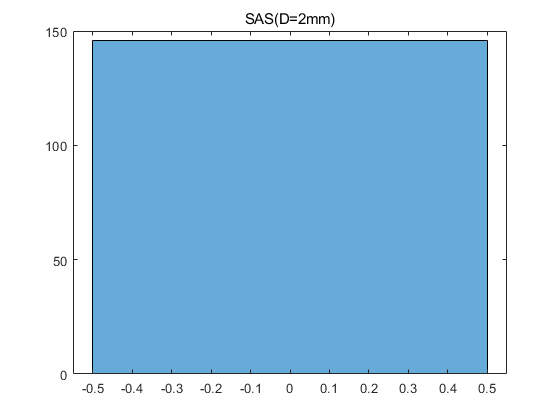

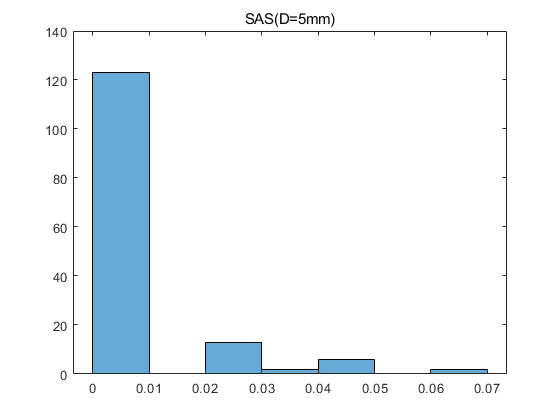

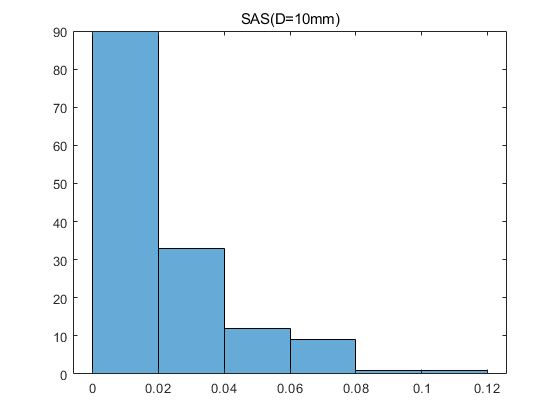

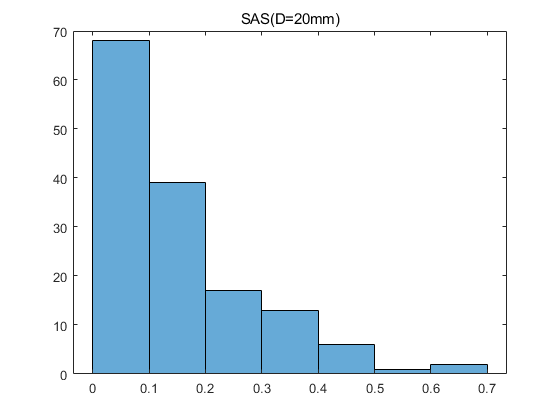


% calculate mean field area (VMAT_PLN_INFO.MFA)
VMAT_PLN_INFO = Mean_Field_Area(VMAT_PLN_INFO);

% calculate small aperture score (SAS) 5mm, 10mm, 20mm 
VMAT_PLN_INFO = Small_Aperture_Score(VMAT_PLN_INFO,BLD_type);

This is 1th cp and 1th iteration 
 This is 1th cp and 2th iteration 
 This is 1th cp and 3th iteration 
 This is 1th cp and 4th iteration 
 This is 1th cp and 5th iteration 
 This is 1th cp and 6th iteration 
 This is 1th cp and 7th iteration 
 This is 1th cp and 8th iteration 
 This is 1th cp and 9th iteration 
 This is 1th cp and 10th iteration 
 This is 2th cp and 1th iteration 
 This is 2th cp and 2th iteration 
 This is 2th cp and 3th iteration 
 This is 2th cp and 4th iteration 
 This is 2th cp and 5th iteration 
 This is 2th cp and 6th iteration 
 This is 2th cp and 7th iteration 
 This is 2th cp and 8th iteration 
 This is 2th cp and 9th iteration 
 This is 2th cp and 10th iteration 
 This is 3th cp and 1th iteration 
 This is 3th cp and 2th iteration 
 This is 3th cp and 3th iteration 
 This is 3th cp and 4th iteration 
 This is 3th cp and 5th iteration 
 This is 3th cp and 6th iteration 
 This is 3th cp and 7th iteration 
 This is 3th cp and 8th iteration 
 This is 3th cp and

VMAT_PLN_INFO = 包含以下字段的 struct :
                       Total_MU: 643.4896
                      Total_CPs: 147
                             FX: 28
                            TPD: 61.6000
                        CP_info: {147×4 cell}
                  MLC_speed_std: [160×1 double]
                        MI_S_02: 15.7708
                        MI_S_05: 31.3441
                         MI_S_1: 49.5886
                         MI_S_2: 71.5814
                  MLC_speed_mat: [160×146 double]
               CP_time_interval: [146×1 double]
                            ALS: 8.4088
                            SLS: 14.4852
           MLC_acceleration_mat: [160×145 double]
           MLC_acceleration_std: [160×1 double]
               MI_Accelerate_02: 17.6368
               MI_Accelerate_05: 36.8837
                MI_Accelerate_1: 60.3743
                MI_Accelerate_2: 86.1776
                            ALA: 15.1678
                            SLA: 14.3825
          MI_TotalModulation_0

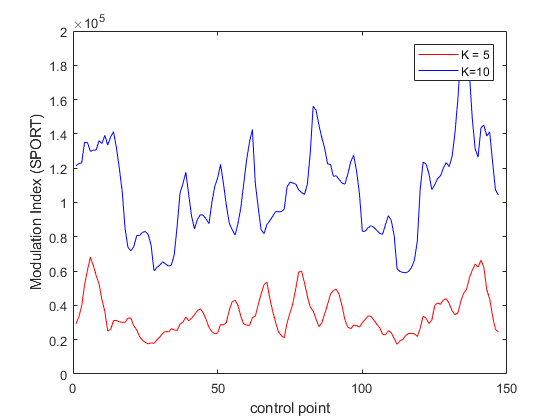


% calculate mean asymmetry distance (VMAT_PLN_INFO.MAD)
VMAT_PLN_INFO = Mean_Asymmetry_Distance(VMAT_PLN_INFO,BLD_type);

% calculate leaf sequence variability (VMAT_PLN_INFO.LSV)
VMAT_PLN_INFO = Leaf_Sequence_Variability(VMAT_PLN_INFO,BLD_type);

% calculate aperture area variability (VMAT_PLN_INFO.AAV)
VMAT_PLN_INFO = Aperture_Area_Variability(VMAT_PLN_INFO,BLD_type);

% calculate Modulation complex score (VMAT_PLN_INFO.MCS)
VMAT_PLN_INFO = Modulation_Complexity_Score(VMAT_PLN_INFO);

% calculate plan related metrics including PA,PI,PM,PMU
VMAT_PLN_INFO = PLAN_PI_PA_PM_PMU(VMAT_PLN_INFO,BLD_type);

% calculate plan edge metric 
VMAT_PLN_INFO = Edge_Metric(VMAT_PLN_INFO,BLD_type);

% calculate Average Leaf Travel (VMAT_PLN_INFO.LT)
VMAT_PLN_INFO = Leaf_Travel(VMAT_PLN_INFO,BLD_type);

% calculate Average Leaf Travel (VMAT_PLN_INFO.LT)
VMAT_PLN_INFO = LTMCS(VMAT_PLN_INFO);

% calculate Modulation Index proposed by Xinglei and Li ruijiang (VMAT_PLN_INFO.MI_XING) [undo]
VMAT_PLN_INFO = MI_SPORT(VMAT_PLN_INFO)


% calculate Converted Aperture metric (VMAT_PLN_INFO.CAM) [undo]
VMAT_PLN_INFO = Converted_Aperture(VMAT_PLN_INFO)

VMAT_PLN_INFO = 包含以下字段的 struct :
                       Total_MU: 643.4896
                      Total_CPs: 147
                             FX: 28
                            TPD: 61.6000
                        CP_info: {147×4 cell}
                  MLC_speed_std: [160×1 double]
                        MI_S_02: 15.7708
                        MI_S_05: 31.3441
                         MI_S_1: 49.5886
                         MI_S_2: 71.5814
                  MLC_speed_mat: [160×146 double]
               CP_time_interval: [146×1 double]
                            ALS: 8.4088
                            SLS: 14.4852
           MLC_acceleration_mat: [160×145 double]
           MLC_acceleration_std: [160×1 double]
               MI_Accelerate_02: 17.6368
               MI_Accelerate_05: 36.8837
                MI_Accelerate_1: 60.3743
                MI_Accelerate_2: 86.1776
                            ALA: 15.1678
                            SLA: 14.3825
          MI_TotalModulation_0


% calculate Edge Area metric (VMAT_PLN_INFO.EAM) [undo]
VMAT_PLN_INFO = Edge_Area(VMAT_PLN_INFO)

未定义与 'struct' 类型的输入参数相对应的函数 'Edge_Area'。


% calculate Circumference/area (VMAT_PLN_INFO.C/A) [undo]
VMAT_PLN_INFO = Circumference_Area(VMAT_PLN_INFO)




## TEST SPEED with TRF

% trf2csv file
% TRF_DATA = [path,'/example/test_case/VMAT1Arc/VMAT202003181Arc_.mat'];
% VMAT_PLN_INFO = TRFLog_Analysis(TRF_DATA,VMAT_PLN_INFO);

% TRF log file MU density comparison
TRF_INFO = MU_density_TRF(inputArg1,inputArg2);

% 

## Export to CSV

csv_path = 'Metrics_table.csv';
data_path = 'C:\GitFolder\VMAT-QA-metrics\example\test_case\';
mat_names = dir([data_path,'*.mat']);
row_names = {'Edge metric (EM)',...
             'Union aperture area (UAA) cm^2',...
             'Plan normalized MU (PMU)',...
             'Plan modulation (PM)',...
             'Plan irregularity (PI)',...
             'Plan area (PA)',...
             'Aperture area variability (AAV)',...
             'Leaf sequence variability (LSV)',...
             'Modulation complexity score (MCS)',...
             'Mean asymmetry distance (MAD) mm',...
             'Small aperture score (SAS) K = 2',...
             'Small aperture score (SAS) K = 5',...
             'Small aperture score (SAS) K = 10',...
             'Small aperture score (SAS) K = 20',...
             'Standard deviation of leaf acceleration (SLA) mm/s^2',...
             'Average leaf acceleration (ALA) mm/s^2',...
             'Standard deviation of leaf speed (SLS) mm/s',...
             'Average leaf speed (ALS) mm/s',...
             'Average leaf travel distance (LT) mm',...
             'Combination of LT and MCS (LTMCS)',...
             'Average dose rate (ADR) MU/s',...
             'Standard deviation of dose rate (SDR) MU/s',...
             'Modulation index for leaf speed (f=0.2)',...
             'Modulation index for leaf speed (f=0.5)',...
             'Modulation index for leaf speed (f=1)',...
             'Modulation index for leaf speed (f=2)',...
             'Modulation index for leaf acceleration (f=0.2)',...
             'Modulation index for leaf acceleration (f=0.5)',...
             'Modulation index for leaf acceleration (f=1)',...
             'Modulation index for leaf acceleration (f=2)',...
             'Modulation index for total modulation(f=0.2)',...
             'Modulation index for total modulation(f=0.5)',...
             'Modulation index for total modulation(f=1)',...
             'Modulation index for total modulation(f=2)'};
for k=1:size(mat_names,1)
    
    load(mat_names(k).name);
    
    X = split(mat_names(k).name,'.');
    S = X{1,1}; title{1,k} = S;
    eval(['data(1,k) = ',S,'.EM;']); 
    eval(['data(2,k) = ',S,'.UAA;']);
    eval(['data(3,k) = ',S,'.PMU;']);
    eval(['data(4,k) = ',S,'.PM;']);
    eval(['data(5,k) = ',S,'.PI;']);
    eval(['data(6,k) = ',S,'.PA;']);
    eval(['data(7,k) = ',S,'.AAV_weighted;']); 
    eval(['data(8,k) = ',S,'.LSV_weighted;']);
    eval(['data(9,k) = ',S,'.MCS;']);
    eval(['data(10,k) = ',S,'.MAD;']);
    eval(['data(11,k) = ',S,'.SAS.Distance_02;']);
    eval(['data(12,k) = ',S,'.SAS.Distance_05;']);
    eval(['data(13,k) = ',S,'.SAS.Distance_10;']);
    eval(['data(14,k) = ',S,'.SAS.Distance_20;']);
    eval(['data(15,k) = ',S,'.SLA;']);
    eval(['data(16,k) = ',S,'.ALA;']);
    eval(['data(17,k) = ',S,'.SLS;']);
    eval(['data(18,k) = ',S,'.ALS;']);
    eval(['data(19,k) = ',S,'.LT;']);
    eval(['data(20,k) = ',S,'.LTMCS;']);
    eval(['data(21,k) = ',S,'.ADR;']);
    eval(['data(22,k) = ',S,'.SDR;']);
    eval(['data(23,k) = ',S,'.MI_S_02;']);eval(['data(24,k) = ',S,'.MI_S_05;']);eval(['data(25,k) = ',S,'.MI_S_1;']);eval(['data(26,k) = ',S,'.MI_S_2;']);
    eval(['data(27,k) = ',S,'.MI_Accelerate_02;']);eval(['data(28,k) = ',S,'.MI_Accelerate_05;']);eval(['data(29,k) = ',S,'.MI_Accelerate_1;']);eval(['data(30,k) = ',S,'.MI_Accelerate_2;']);
    eval(['data(31,k) = ',S,'.MI_TotalModulation_02;']);eval(['data(32,k) = ',S,'.MI_TotalModulation_05;']);eval(['data(33,k) = ',S,'.MI_TotalModulation_1;']);eval(['data(34,k) = ',S,'.MI_TotalModulation_2;']);
end

table_data = array2table(data);
table_data.Properties.VariableNames = title;
table_data.Properties.RowNames= row_names;
writetable(table_data, [cd,'\',csv_path],'WriteRowNames',true);